# Cross-Temporal Decoding

fileDirs = [{'D:\WorkBigDataFiles\PFC\GE11_Session132'},...
    {'D:\WorkBigDataFiles\PFC\GE13_Session083'},...
    {'D:\WorkBigDataFiles\PFC\GE14_Session123'},...
    {'D:\WorkBigDataFiles\PFC\GE17_Session095'},...
    {'D:\WorkBigDataFiles\PFC\GE24_Session096'}];

% fileDirs = [{'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE11_Session146'},...
%     {'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE13_Session103'},...
%     {'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE17_Session110'}];

% fileDirs = [{'D:\WorkBigDataFiles\PFC\GE11_Session132'},...
%     {'D:\WorkBigDataFiles\PFC\GE13_Session083'},...
%     {'D:\WorkBigDataFiles\PFC\GE14_Session123'},...
%     {'D:\WorkBigDataFiles\PFC\GE17_Session095'},...
%     {'D:\WorkBigDataFiles\PFC\GE24_Session096'},...
%     {'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE11_Session146'},...
%     {'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE13_Session103'},...
%     {'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE17_Session110'}];

binSize = 200;
dsRate = 50;
trlWindow = {[-3000 3000]};
% alignment = {'PokeIn'};
alignment = {'PokeOut'};
% alignment = {'RewardSignal'};
% alignment = {'FrontReward'};
bayesType = 1; % bayesType: 1 = Poisson: use with raw spike counts; 2 = Bernoulli: use with binarized spike counts; 3 = Gaussian: Use with z-scored spike counts
endTrialBound = 'PO';
% endTrialBound = 'RS';
% endTrialBound = 'RWD';

lfpWindow = [16 32];

numChancePerms = 10;

postCLim = [0 0.05];

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);
%#ok<*UNRCH>
rbDivMap = diverging_map(0:0.01:1,[0 0.4 0.8], [0.8 0 0.4]);

## Compile Data

tic;
for ani = 1:length(fileDirs)
    % Create & setup initial object and data variables (if initial file)
    mlb = MLB_SM(fileDirs{ani});
    % Create Analysis Variables
    if ani == 1
        % Hold Durations
        trialInfo = cell(mlb.seqLength,1,length(fileDirs));
        trialHoldDurs = cell(length(fileDirs),1);
        trialRwdLats = cell(length(fileDirs),1);
        trialLIGHTlat = cell(length(fileDirs),1);
        trialPIlat = cell(length(fileDirs),1);
        trialSIGlat = cell(length(fileDirs),1);
        trialPOlat = cell(length(fileDirs),1);
        trialRWDlat = cell(length(fileDirs),1);
        nxtTrlLats = cell(length(fileDirs),1);
        prevTrlLats = cell(length(fileDirs),1);
        % Real Posteriors
        trlHRs = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        trlFARs = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        trlDs = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        persFit_Trial = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        persFit_Interval = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        dec_Within = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        dec_Across = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        dec_TrPrTsPo = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        dec_TrPoTsPr = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        dec_TrPrTsTrl = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        dec_TrPoTsTrl = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        dec_TrTrlTsPr = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        dec_TrTrlTsPo = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        dec_TrTrlTsPrCON = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        dec_TrTrlTsPoCON = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        dec_TrPr = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        dec_TrTr = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        dec_TrPo = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        dec_TrPrCON = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        dec_TrTrCON = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        dec_TrPoCON = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        % Chance Posteriors
        chancePDF = cell(length(mlb.odrVect), 1);
        chanceOdr = cell(length(mlb.odrVect), 1);
        % Beta Power
        lfpPower = cell(mlb.seqLength, length(fileDirs));
        lfpPhase = cell(mlb.seqLength, length(fileDirs));
    end
    mlb.binSize = binSize;
    mlb.dsRate = dsRate;
    mlb.windows = trlWindow;
    mlb.bayesType = 1;
    mlb.alignments = alignment;

    % Process Port Entry Aligned Observations
    mlb.SetLikes_ISC;
    mlb.Process_IterativeLikelyL1O;
    if length(mlb.odrVect)~=mlb.seqLength
        temp = mlb.post;
        listLog = mlb.odrVect<10;
        mlb.post = cat(3,temp(listLog,:,:), temp(~listLog,:,:));
        temp = mlb.postTrlIDs;
        mlb.postTrlIDs = [temp(listLog,:), temp(~listLog,:)];
    end


    % Pull out Trial info
    for p = 1:mlb.seqLength
        pti = mlb.postTrlIDs(p,:);
        trialInfo{p,1,ani} = mlb.trialInfo(pti(~isnan(pti)));
    end
    % Pull out Trial Variables
    tmpSFPtrlIDs = mlb.postTrlIDs;
    tmpSFPtrlIDs(1,:) = [];
    if strcmp(alignment{1}, 'PokeIn')
        trialLIGHTlat{ani} = ([mlb.trialInfo(tmpSFPtrlIDs(~isnan(tmpSFPtrlIDs))).PortLightIndex] - [mlb.trialInfo(tmpSFPtrlIDs(~isnan(tmpSFPtrlIDs))).PokeInIndex])/mlb.sampleRate;
        trialPIlat{ani} = ([mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PokeInIndex] - [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PokeInIndex])/mlb.sampleRate;
        trialSIGlat{ani} = ([mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).RewardSignalIndex] - [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PokeInIndex])/mlb.sampleRate;
        trialPOlat{ani} = ([mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PokeOutIndex] - [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PokeInIndex])/mlb.sampleRate;
        trialRWDlat{ani} = ([mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).RewardIndex] - [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PokeInIndex])/mlb.sampleRate;
    elseif strcmp(alignment{1}, 'RewardSignal')
        trialLIGHTlat{ani} = ([mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PortLightIndex] - [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).RewardSignalIndex])/mlb.sampleRate;
        trialPIlat{ani} = ([mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PokeInIndex] - [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).RewardSignalIndex])/mlb.sampleRate;
        trialSIGlat{ani} = ([mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).RewardSignalIndex] - [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).RewardSignalIndex])/mlb.sampleRate;
        trialPOlat{ani} = ([mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PokeOutIndex] - [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).RewardSignalIndex])/mlb.sampleRate;
        trialRWDlat{ani} = ([mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).RewardIndex] - [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).RewardSignalIndex])/mlb.sampleRate;
    elseif strcmp(alignment{1}, 'PokeOut')
        trialLIGHTlat{ani} = ([mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PortLightIndex] - [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PokeOutIndex])/mlb.sampleRate;
        trialPIlat{ani} = ([mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PokeInIndex] - [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PokeOutIndex])/mlb.sampleRate;
        trialSIGlat{ani} = ([mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).RewardSignalIndex] - [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PokeOutIndex])/mlb.sampleRate;
        trialPOlat{ani} = ([mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PokeOutIndex] - [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PokeOutIndex])/mlb.sampleRate;
        trialRWDlat{ani} = ([mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).RewardIndex] - [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PokeOutIndex])/mlb.sampleRate;
    elseif strcmp(alignment{1}, 'FrontReward')
        trialLIGHTlat{ani} = ([mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PortLightIndex] - [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).RewardIndex])/mlb.sampleRate;
        trialPIlat{ani} = ([mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PokeInIndex] - [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).RewardIndex])/mlb.sampleRate;
        trialSIGlat{ani} = ([mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).RewardSignalIndex] - [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).RewardIndex])/mlb.sampleRate;
        trialPOlat{ani} = ([mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PokeOutIndex] - [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).RewardIndex])/mlb.sampleRate;
        trialRWDlat{ani} = ([mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).RewardIndex] - [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).RewardIndex])/mlb.sampleRate;
    end
    % Hold Duration
    trialHoldDurs{ani} = [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PokeDuration];
    % Reward Latency
    trialRwdLats{ani} = ([mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).RewardIndex] - [mlb.trialInfo(mlb.postTrlIDs(~isnan(mlb.postTrlIDs))).PokeInIndex])/mlb.sampleRate;
    % Adjacent trial boundary times
    nonTermPosTrls = mlb.postTrlIDs(1:mlb.seqLength-1,:);
    nonTermPosTrls = nonTermPosTrls(~isnan(nonTermPosTrls));
    temp_NextTrls = nonTermPosTrls+1;
    nxtTrlLog = temp_NextTrls<=length(mlb.trialInfo);
    nonFrstPosTrls = mlb.postTrlIDs(2:mlb.seqLength,:);
    nonFrstPosTrls = nonFrstPosTrls(~isnan(nonFrstPosTrls));
    temp_PrevTrls = nonFrstPosTrls-1;
    prevTrlLog = temp_PrevTrls>=1; % Should always be after removing position 1 but just to be safe...
    if strcmp(endTrialBound, 'RWD') || strcmp(alignment{1}, 'FrontReward')
        nxtTrlLats{ani} = ([mlb.trialInfo(temp_NextTrls(nxtTrlLog)).PokeInIndex] - [mlb.trialInfo(nonTermPosTrls(nxtTrlLog)).RewardIndex])/mlb.sampleRate;
        prevTrlLats{ani} = ([mlb.trialInfo(temp_PrevTrls(prevTrlLog)).RewardIndex] - [mlb.trialInfo(nonFrstPosTrls(prevTrlLog)).PokeInIndex])/mlb.sampleRate;
    elseif strcmp(endTrialBound, 'PO')
        nxtTrlLats{ani} = ([mlb.trialInfo(temp_NextTrls(nxtTrlLog)).PokeInIndex] - [mlb.trialInfo(nonTermPosTrls(nxtTrlLog)).PokeOutIndex])/mlb.sampleRate;
        prevTrlLats{ani} = ([mlb.trialInfo(temp_PrevTrls(prevTrlLog)).PokeOutIndex] - [mlb.trialInfo(nonFrstPosTrls(prevTrlLog)).PokeInIndex])/mlb.sampleRate;
    elseif strcmp(endTrialBound, 'RS')
        nxtTrlLats{ani} = ([mlb.trialInfo(temp_NextTrls(nxtTrlLog)).PokeInIndex] - [mlb.trialInfo(nonTermPosTrls(nxtTrlLog)).RewardSignalIndex])/mlb.sampleRate;
        prevTrlLats{ani} = ([mlb.trialInfo(temp_PrevTrls(prevTrlLog)).RewardSignalIndex] - [mlb.trialInfo(nonFrstPosTrls(prevTrlLog)).PokeInIndex])/mlb.sampleRate;
    end


    % First, to avoid nans and infinites any values that are ==1 or ==0 need to be replaced with the next nearest value
    allVals = unique([mlb.post{:}]);
    if min(allVals)==0
        minVal = allVals(2);
    else
        minVal = allVals(1);
    end
    if max(allVals)==1
        maxVal = allVals(end-1);
    else
        maxVal = allVals(end);
    end
    clear allVals;

    [temp_lfpPhase, temp_lfpPower] = mlb.PP_TrialMatrix_LFP(lfpWindow, trlWindow{1}, alignment{1});
    for p1 = 1:mlb.seqLength
        tempTrlIDs = mlb.postTrlIDs(p1,:);
        tempTrlIDs(isnan(tempTrlIDs)) = [];
        lfpPhase{p1,ani} = squeeze(temp_lfpPhase(:,:,[mlb.trialInfo(tempTrlIDs).TrialNum]));
        lfpPower{p1,ani} = squeeze(temp_lfpPower(:,:,[mlb.trialInfo(tempTrlIDs).TrialNum]));
        for p2 = 1:mlb.seqLength
            % Calculate Hit Rates
            temp_tempHRs = mlb.post(p1,1,:);
            temp_tempHRs(cellfun(@(a)isempty(a),temp_tempHRs)) = [];
            temp_temp_tempHRs = cell2mat(cellfun(@(a){a(:,:,p2)}, temp_tempHRs));
            temp_temp_tempHRs(temp_temp_tempHRs==0) = minVal;
            temp_temp_tempHRs(temp_temp_tempHRs==1) = maxVal;
            trlHRs{p1,p2,ani} = temp_temp_tempHRs;
            % Calculate False Alarm Rates
            %             faLog = (1:mlb.seqLength ~= p1) & (1:mlb.seqLength ~= p2);
            faLog = (1:mlb.seqLength ~= p1);
            temp_tempFARs = reshape(squeeze(mlb.post(faLog,1,:)), [1,1,numel(mlb.post)-(size(mlb.post,3)*sum(~faLog))]);
            temp_tempFARs(cellfun(@(a)isempty(a),temp_tempFARs)) = [];
            temp_temp_tempFARs = repmat(mean(cell2mat(cellfun(@(a){a(:,:,p2)},temp_tempFARs)),3,'omitnan'), [1,1,size(temp_tempHRs,3)]);
            temp_temp_tempFARs(temp_temp_tempFARs==0) = minVal;
            temp_temp_tempFARs(temp_temp_tempFARs==1) = maxVal;
            trlFARs{p1,p2,ani} = temp_temp_tempFARs;
            % Calculate d'
            temp_aniDs = norminv(temp_temp_tempHRs) - norminv(temp_temp_tempFARs);
            %             temp_aniDs = temp_temp_tempHRs - temp_temp_tempFARs;
            trlDs{p1,p2,ani} = temp_aniDs;

            % Analyze trial data
            temp_persFit_Trial = nan(size(temp_aniDs,3), length(mlb.obsvTimeVect));     % Persistence model fit Trial period
            temp_persFit_Interval = nan(size(temp_aniDs,3), length(mlb.obsvTimeVect));       % Persistence model fit ITI period\
            temp_dec_Within = nan(size(temp_aniDs,3),1);
            temp_dec_Across =  nan(size(temp_aniDs,3),1);
            temp_dec_TrPrTsPo = nan(size(temp_aniDs,3), length(mlb.obsvTimeVect));
            temp_dec_TrPoTsPr = nan(size(temp_aniDs,3), length(mlb.obsvTimeVect));
            temp_dec_TrPrTsTrl = nan(size(temp_aniDs,3), length(mlb.obsvTimeVect));
            temp_dec_TrPoTsTrl = nan(size(temp_aniDs,3), length(mlb.obsvTimeVect));
            temp_dec_TrTrlTsPr = nan(size(temp_aniDs,3), length(mlb.obsvTimeVect));
            temp_dec_TrTrlTsPo = nan(size(temp_aniDs,3), length(mlb.obsvTimeVect));
            temp_dec_TrTrlTsPrCON = nan(size(temp_aniDs,3), length(mlb.obsvTimeVect));
            temp_dec_TrTrlTsPoCON = nan(size(temp_aniDs,3), length(mlb.obsvTimeVect));
            temp_dec_TrPr = nan(size(temp_aniDs,3), length(mlb.obsvTimeVect));
            temp_dec_TrTr = nan(size(temp_aniDs,3), length(mlb.obsvTimeVect));
            temp_dec_TrPo = nan(size(temp_aniDs,3), length(mlb.obsvTimeVect));
            temp_dec_TrPrCON = nan(size(temp_aniDs,3), length(mlb.obsvTimeVect));
            temp_dec_TrPoCON = nan(size(temp_aniDs,3), length(mlb.obsvTimeVect));

            for trl = 1:length(tempTrlIDs)
                curTrlInfo = mlb.trialInfo(tempTrlIDs(trl));
                % First, define the trial boundaries:
                % i.e. when the trial starts (tStart) and ends (tEnd)
                % These values vary based on the way the trial is aligned, and what feature is used as the trial end boundary
                if strcmp(alignment{1}, 'PokeIn')
                    tStart = 0;
                    if strcmp(endTrialBound, 'PO')
                        tEnd = curTrlInfo.PokeDuration;
                    elseif strcmp(endTrialBound, 'RWD')
                        tEnd = (curTrlInfo.RewardIndex - curTrlInfo.PokeInIndex)/mlb.sampleRate;
                    end
                elseif strcmp(alignment{1}, 'PokeOut')
                    tStart = curTrlInfo.PokeDuration*-1;
                    if strcmp(endTrialBound, 'PO')
                        tEnd = 0;
                    elseif strcmp(endTrialBound, 'RWD')
                        tEnd = (curTrlInfo.RewardIndex - curTrlInfo.PokeOutIndex)/mlb.sampleRate;
                    end
                elseif strcmp(alignment{1}, 'RewardSignal')
                    tStart = (curTrlInfo.PokeInIndex - curTrlInfo.RewardSignalIndex)/mlb.sampleRate;
                    if strcmp(endTrialBound, 'PO')
                        tEnd = (curTrlInfo.PokeOutIndex - curTrlInfo.RewardSignalIndex)/mlb.sampleRate;
                    elseif strcmp(endTrialBound, 'RWD')
                        tEnd = (curTrlInfo.RewardIndex - curTrlInfo.RewardSignalIndex)/mlb.sampleRate;
                    elseif strcmp(endTrialBound, 'RS')
                        tEnd = 0;
                    end
                elseif strcmp(alignment{1}, 'FrontReward')
                    tStart = (curTrlInfo.PokeInIndex - curTrlInfo.RewardIndex)/mlb.sampleRate;
                    if strcmp(endTrialBound, 'PO')
                        tEnd = (curTrlInfo.PokeOutIndex - curTrlInfo.RewardIndex)/mlb.sampleRate;
                    elseif strcmp(endTrialBound, 'RWD')
                        tEnd = 0;
                    end
                end
                curTrlD = temp_aniDs(:,:,trl);
                % Next define the Interval Boundaries
                % If it's position 1 or the end of the sequence replace the pre-trial (pos1) or post-trial (posEnd) with 800ms (default interval lockout time)
                if p1 == 1
                    preTrlIntervalDur = 0.8;
                else
                    if strcmp(endTrialBound, 'RWD')
                        preTrlIntervalDur = (curTrlInfo.PokeInIndex - mlb.trialInfo(curTrlInfo.TrialNum-1).RewardIndex)/mlb.sampleRate;
                    elseif strcmp(endTrialBound, 'PO')
                        preTrlIntervalDur = (curTrlInfo.PokeInIndex - mlb.trialInfo(curTrlInfo.TrialNum-1).PokeOutIndex)/mlb.sampleRate;
                    elseif strcmp(endTrialBound, 'RS')
                        preTrlIntervalDur = (curTrlInfo.PokeInIndex - mlb.trialInfo(curTrlInfo.TrialNum-1).RewardSignalIndex)/mlb.sampleRate;
                    end
                end
                if p1 == mlb.seqLength
                    pstTrlIntervalDur = 0.8;
                else
                    if strcmp(endTrialBound, 'RWD')
                        pstTrlIntervalDur = (mlb.trialInfo(curTrlInfo.TrialNum+1).PokeInIndex - curTrlInfo.RewardIndex)/mlb.sampleRate;
                    elseif strcmp(endTrialBound, 'PO')
                        pstTrlIntervalDur = (mlb.trialInfo(curTrlInfo.TrialNum+1).PokeInIndex - curTrlInfo.PokeOutIndex)/mlb.sampleRate;
                    elseif strcmp(endTrialBound, 'RS')
                        pstTrlIntervalDur = (mlb.trialInfo(curTrlInfo.TrialNum+1).PokeInIndex - curTrllInfo.RewardSignalIndex)/mlb.sampleRate;
                    end
                end
                % Define the trial masks based on alignments and interval boundaries from above
                % trialLog      = Trial mask used for... whenever the trial period is examined
                % pers_IntLog   = Full interval mask used for persistance fit measure (pre-trial for PI aligned; post-trial for PO & RWD aligned)
                % perTrl_IntLog = Pre-trial interval mask for decoding with non-overlapping Intervals (defined as 1/2 the duration of the pre-trial interval)
                % pstTrl_IntLog = Post-trial interval mask for decoding with non-overlapping Intervals (defined as 1/2 the duration of the post-trial interval)
                trialLog = (mlb.obsvTimeVect >= tStart) & (mlb.obsvTimeVect < tEnd);
                if strcmp(alignment{1},'PokeIn')
                    pers_IntLog = (mlb.obsvTimeVect < tStart) & (mlb.obsvTimeVect >= preTrlIntervalDur*-1);
                elseif strcmp(alignment{1},'PokeOut') || strcmp(alignment{1},'FrontReward') || strcmp(alignment{1},'RewardSignal')
                    pers_IntLog = (mlb.obsvTimeVect > tEnd) & (mlb.obsvTimeVect <= pstTrlIntervalDur);
                end
                preTrl_IntLog = (mlb.obsvTimeVect < tStart) & (mlb.obsvTimeVect >= (tStart - preTrlIntervalDur/2));
                %                     preTrl_IntLogCON = (mlb.obsvTimeVect < (tStart - preTrlIntervalDur/2)) & (mlb.obsvTimeVect >= (tStart - preTrlIntervalDur));
                preTrl_IntLogCON = (mlb.obsvTimeVect < (tStart - preTrlIntervalDur*.25)) & (mlb.obsvTimeVect >= (tStart - preTrlIntervalDur*.75));
                pstTrl_IntLog = (mlb.obsvTimeVect >= tEnd) & (mlb.obsvTimeVect < (tEnd + pstTrlIntervalDur/2));
                %                     pstTrl_IntLogCON = (mlb.obsvTimeVect >= (tEnd + pstTrlIntervalDur/2)) & (mlb.obsvTimeVect < (tEnd + pstTrlIntervalDur));
                pstTrl_IntLogCON = (mlb.obsvTimeVect >= (tEnd + pstTrlIntervalDur*.25)) & (mlb.obsvTimeVect < (tEnd + pstTrlIntervalDur*.75));

                % Calculate Trial and Interval period persistance fits
                trialDynCap = sum(trialLog)-1;
                trialPeriod = zscore(curTrlD(trialLog,trialLog), 0, 'all');
                for d = 1:trialDynCap-1
                    tempDyn = zscore(triu(true(sum(trialLog)), d*-1) & tril(true(sum(trialLog)), d), 0, 'all');
                    temp_persFit_Trial(trl,d) = pdist([trialPeriod(:)';tempDyn(:)'], 'cosine');
                end
                itiDynCap = sum(pers_IntLog)-1;
                itiPeriod = zscore(curTrlD(pers_IntLog,pers_IntLog), 0 , 'all');
                for d = 1:itiDynCap-1
                    tempDyn = zscore(triu(true(sum(pers_IntLog)), d*-1) & tril(true(sum(pers_IntLog)), d), 0, 'all');
                    temp_persFit_Interval(trl,d) = pdist([itiPeriod(:)';tempDyn(:)'], 'cosine');
                end

                % NOTE: the variable naming convention I'm using here is Train-Test. In Matlab the indexing for arrays is (Row,Column). Because the
                % posteriors are all organized with observed time as the rows and training time as the columns it means the arrays are being indexed
                % as (Test,Train) time. Hence, the inversion of the variable name and the indexing used in the masks. I could change it... and I had
                % in previous versions of the code... but I'm not doing that here to keep everything consistent. I can always transpose the outputs in
                % Illustrator later on.

                % Within vs Across
                % Mask for the Trial epoch
                trialMask = false(size(curTrlD));
                trialMask(trialLog,trialLog) = true;
                % Mask for the Interval epoch
                intervalMask = false(size(curTrlD));
                intervalMask(pers_IntLog,pers_IntLog) = true;
                % Mask for the Trial trained Interval test epoch
                trialIntervalMask = false(size(curTrlD));
                trialIntervalMask(pers_IntLog,trialLog) = true;
                % Mask for the Interval trained Trial test epoch
                intervalTrialMask = false(size(curTrlD));
                intervalTrialMask(trialLog,pers_IntLog) = true;
                % Calculate Within vs Across Epoch Decoding
                temp_dec_Within(trl) = mean(curTrlD(trialMask | intervalMask), 'omitnan');
                temp_dec_Across(trl) = mean(curTrlD(trialIntervalMask | intervalTrialMask), 'omitnan');

                % Calculate Cross-Interval Decoding Using Non-Overlapping Intervals
                % Train Pre-Trial & Test Post-Trial
                temp_temp_dec_TrPrTsPo = curTrlD(pstTrl_IntLog,preTrl_IntLog);
                temp_dec_TrPrTsPo(trl,1:sum(preTrl_IntLog)) = mean(temp_temp_dec_TrPrTsPo, 'omitnan');
                % Train Post-Trial & Train Pre-Trial
                temp_temp_dec_TrPoTsPr = curTrlD(preTrl_IntLog,pstTrl_IntLog);
                temp_dec_TrPoTsPr(trl,end-sum(pstTrl_IntLog)+1:end) = sum(temp_temp_dec_TrPoTsPr, 'omitnan');

                % Calculate Interval Train - Trial Test Decoding
                % Train Pre-trial & Test Trial
                temp_temp_dec_TrPrTsTrl = curTrlD(trialLog,preTrl_IntLog);
                temp_dec_TrPrTsTrl(trl,1:sum(preTrl_IntLog)) = mean(temp_temp_dec_TrPrTsTrl, 'omitnan');
                % Train Post-Trial & Test Trial
                temp_temp_dec_TrPoTsTrl = curTrlD(trialLog,pstTrl_IntLog);
                temp_dec_TrPoTsTrl(trl,end-sum(pstTrl_IntLog)+1:end) = mean(temp_temp_dec_TrPoTsTrl, 'omitnan');

                % Calculate Trial Train - Interval Test Decoding
                % Train Trial & Test Pre-Trial
                temp_temp_dec_TrTrlTsPr = curTrlD(preTrl_IntLog,trialLog);
                temp_temp_dec_TrTrlTsPrCON = curTrlD(preTrl_IntLogCON,trialLog);
                if strcmp(alignment{1},'PokeIn')
                    temp_dec_TrTrlTsPr(trl,1:sum(trialLog)) = mean(temp_temp_dec_TrTrlTsPr, 'omitnan');
                    temp_dec_TrTrlTsPrCON(trl,1:sum(trialLog)) = mean(temp_temp_dec_TrTrlTsPrCON, 'omitnan');
                else
                    temp_dec_TrTrlTsPr(trl,end-sum(trialLog)+1:end) = mean(temp_temp_dec_TrTrlTsPr, 'omitnan');
                    temp_dec_TrTrlTsPrCON(trl,end-sum(trialLog)+1:end) = mean(temp_temp_dec_TrTrlTsPrCON, 'omitnan');
                end
                % Train Trial & Test Post-Trial
                temp_temp_dec_TrTrlTsPo = curTrlD(pstTrl_IntLog,trialLog);
                temp_temp_dec_TrTrlTsPoCON = curTrlD(pstTrl_IntLogCON,trialLog);
                if strcmp(alignment{1},'PokeIn')
                    temp_dec_TrTrlTsPo(trl,1:sum(trialLog)) = mean(temp_temp_dec_TrTrlTsPo, 'omitnan');
                    temp_dec_TrTrlTsPoCON(trl,1:sum(trialLog)) = mean(temp_temp_dec_TrTrlTsPoCON, 'omitnan');
                else
                    temp_dec_TrTrlTsPo(trl,end-sum(trialLog)+1:end) = mean(temp_temp_dec_TrTrlTsPo, 'omitnan');
                    temp_dec_TrTrlTsPoCON(trl,end-sum(trialLog)+1:end) = mean(temp_temp_dec_TrTrlTsPoCON, 'omitnan');
                end
                % Train Pre-Trial
                temp_temp_dec_TrPr = curTrlD(:,preTrl_IntLog);
                temp_dec_TrPr(trl,:) = mean(temp_temp_dec_TrPr,2,'omitnan');
                temp_temp_dec_TrPrCON = curTrlD(:,preTrl_IntLogCON);
                temp_dec_TrPrCON(trl,:) = mean(temp_temp_dec_TrPrCON,2,'omitnan');
                % Train Trial
                temp_temp_dec_TrTr = curTrlD(:,trialLog);
                temp_dec_TrTr(trl,:) = mean(temp_temp_dec_TrTr,2,'omitnan');
                % Train Post-Trial
                temp_temp_dec_TrPo = curTrlD(:,pstTrl_IntLog);
                temp_dec_TrPo(trl,:) = mean(temp_temp_dec_TrPo,2,'omitnan');
                temp_temp_dec_TrPoCON = curTrlD(:,pstTrl_IntLogCON);
                temp_dec_TrPoCON(trl,:) = mean(temp_temp_dec_TrPoCON,2,'omitnan');
            end
            persFit_Trial{p1,p2,ani} = temp_persFit_Trial;
            persFit_Interval{p1,p2,ani} = temp_persFit_Interval;
            dec_Within{p1,p2,ani} = temp_dec_Within;
            dec_Across{p1,p2,ani} = temp_dec_Across;
            dec_TrPrTsPo{p1,p2,ani} = temp_dec_TrPrTsPo;
            dec_TrPoTsPr{p1,p2,ani} = temp_dec_TrPoTsPr;
            dec_TrPrTsTrl{p1,p2,ani} = temp_dec_TrPrTsTrl;
            dec_TrPoTsTrl{p1,p2,ani} = temp_dec_TrPoTsTrl;
            dec_TrTrlTsPr{p1,p2,ani} = temp_dec_TrTrlTsPr;
            dec_TrTrlTsPo{p1,p2,ani} = temp_dec_TrTrlTsPo;
            dec_TrTrlTsPrCON{p1,p2,ani} = temp_dec_TrTrlTsPrCON;
            dec_TrTrlTsPoCON{p1,p2,ani} = temp_dec_TrTrlTsPoCON;
            dec_TrPr{p1,p2,ani} = temp_dec_TrPr;
            dec_TrTr{p1,p2,ani} = temp_dec_TrTr;
            dec_TrPo{p1,p2,ani} = temp_dec_TrPo;
            dec_TrPrCON{p1,p2,ani} = temp_dec_TrPrCON;
            dec_TrPoCON{p1,p2,ani} = temp_dec_TrPoCON;
        end
    end
    toc
end

Compiling StatMatrix Data....Completed


Compiling LFP


Elapsed time is 124.622737 seconds.


Compiling StatMatrix Data....Completed


Compiling LFP


Elapsed time is 387.343316 seconds.


Compiling StatMatrix Data....Completed


Compiling LFP


Elapsed time is 519.267125 seconds.


Compiling StatMatrix Data....Completed


Compiling LFP


Elapsed time is 689.507459 seconds.


Compiling StatMatrix Data....Completed


Compiling LFP


Elapsed time is 797.694862 seconds.


toc

Elapsed time is 797.697144 seconds.


objTimeVect = mlb.obsvTimeVect-mlb.obsvTimeVect(1);

## Combine Trials Across Rats

groupHRs = cell(mlb.seqLength);
groupFARs = cell(mlb.seqLength);
groupDs = cell(mlb.seqLength);
for p1 = 1:mlb.seqLength
    for p2 = 1:mlb.seqLength
        groupHRs{p1,p2} = cell2mat(trlHRs(p1,p2,:));
        groupFARs{p1,p2} = cell2mat(trlFARs(p1,p2,:));
        groupDs{p1,p2} = cell2mat(trlDs(p1,p2,:));
    end
end


## D' Plots

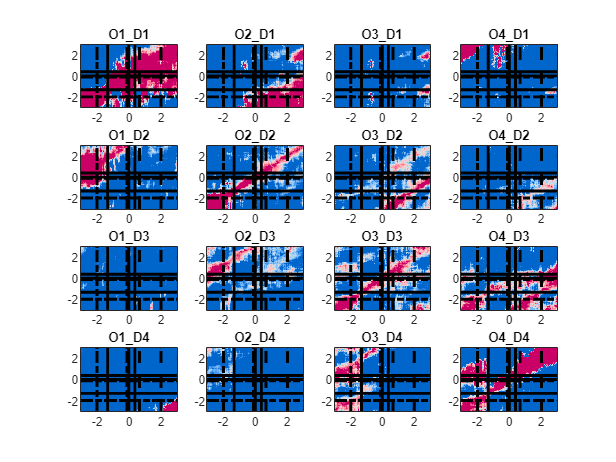

% for z = 1:numel(groupHRs); subplot(4,4,z); imagesc(mean(groupHRs{z},3));end
% figure;
% for z = 1:numel(groupHRs); subplot(4,4,z); imagesc(mean(groupFARs{z},3));end
figure;
for z = 1:numel(groupHRs)
    subplot(4,4,z);
    %     imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,median(zscore(groupDs{z},0,'all'),3), [-1 1]);
    imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,median(groupDs{z},3), [-0.5 0.5]);
    colormap(rbDivMap);
    hold on;
    set(gca, 'ydir', 'normal');
    [r,c] = ind2sub(mlb.seqLength, z);
    title(sprintf('O%i_D%i',r,c), 'interpreter', 'none');
    plot(repmat(median(cell2mat(trialLIGHTlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(get(gca,'xlim'), repmat(median(cell2mat(trialLIGHTlat(:)')), [1,2]), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialPIlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(get(gca,'xlim'), repmat(median(cell2mat(trialPIlat(:)')), [1,2]), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(get(gca,'xlim'), repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialPOlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(get(gca,'xlim'), repmat(median(cell2mat(trialPOlat(:)')), [1,2]), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(get(gca,'xlim'), repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), '-k', 'linewidth', 2);
    if strcmp(endTrialBound, 'RWD')
        plot(repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'PO')
        plot(repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'RS')
        plot(repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    end
    plot(repmat(median(cell2mat(trialPIlat(:)')) - median(cell2mat(prevTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
end


presentDs = reshape(groupDs(logical(eye(mlb.seqLength))), [1,1,mlb.seqLength]);
pastDs = reshape(groupDs(triu(true(mlb.seqLength),-1) & tril(true(mlb.seqLength),-1)),[1,1,mlb.seqLength-1]);
futureDs = reshape(groupDs(triu(true(mlb.seqLength),1) & tril(true(mlb.seqLength),1)),[1,1,mlb.seqLength-1]);


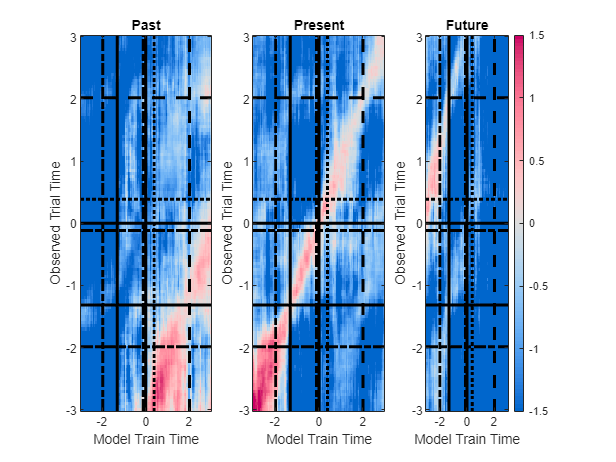


figure;
sp = nan(1,3);
sp(1) = subplot(1,3,1);
% imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,mean(cell2mat(pastDs),3),[-1.5 1.5]);
% imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,mean(zscore(cell2mat(pastDs),0,'all'),3),[-0.5 0.5]);
imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,mean(cell2mat(pastDs(1:end-1)),3),[-1.5 1.5]);
% imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,median(zscore(cell2mat(pastDs(1:end-1)),0,'all'),3),[-0.5 0.5]);
hold on;
set(gca,'ydir', 'normal');
colormap(cMap);
xlabel('Model Train Time');
ylabel('Observed Trial Time');
title('Past');
sp(2) = subplot(1,3,2);
% imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,mean(cell2mat(presentDs),3),[-1.5 1.5]);
% imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,mean(zscore(cell2mat(presentDs),0,'all'),3),[-0.5 0.5]);
imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,mean(cell2mat(presentDs(2:3)),3),[-1.5 1.5]);
% imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,median(zscore(cell2mat(presentDs(2:3)),0,'all'),3),[-0.5 0.5]);
hold on;
set(gca,'ydir', 'normal');
colormap(cMap);
xlabel('Model Train Time');
ylabel('Observed Trial Time');
title('Present');
sp(3) = subplot(1,3,3);
% imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,mean(cell2mat(futureDs),3),[-1.5 1.5]);
% imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,mean(zscore(cell2mat(futureDs),0,'all'),3),[-0.5 0.5]);
imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,mean(cell2mat(futureDs(2:end)),3),[-1.5 1.5]);
% imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,median(zscore(cell2mat(futureDs(2:end)),0,'all'),3),[-0.5 0.5]);
hold on;
set(gca,'ydir', 'normal');
% colormap(cMap);
colormap(rbDivMap);
xlabel('Model Train Time');
ylabel('Observed Trial Time');
title('Future');
colorbar
for p = 1:length(sp)
    plot(sp(p), repmat(median(cell2mat(trialLIGHTlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(sp(p), get(gca,'xlim'), repmat(median(cell2mat(trialLIGHTlat(:)')), [1,2]), '-.k', 'linewidth', 2);
    plot(sp(p), repmat(median(cell2mat(trialPIlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(sp(p), get(gca,'xlim'), repmat(median(cell2mat(trialPIlat(:)')), [1,2]), '-k', 'linewidth', 2);
    plot(sp(p), repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(sp(p), get(gca,'xlim'), repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), '-.k', 'linewidth', 2);
    plot(sp(p), repmat(median(cell2mat(trialPOlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(sp(p), get(gca,'xlim'), repmat(median(cell2mat(trialPOlat(:)')), [1,2]), '-k', 'linewidth', 2);
    plot(sp(p), repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 2);
    plot(sp(p), get(gca,'xlim'), repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), ':k', 'linewidth', 2);
    if strcmp(endTrialBound, 'RWD')
        plot(sp(p), repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
        plot(sp(p), get(gca,'xlim'), repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'PO')
        plot(sp(p), repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
        plot(sp(p), get(gca,'xlim'), repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'RS')
        plot(sp(p), repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
        plot(sp(p),  get(gca,'xlim'), repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), '--k', 'linewidth', 2);
    end
    plot(sp(p), repmat(median(cell2mat(trialPIlat(:)')) + median(cell2mat(prevTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(sp(p), get(gca,'xlim'), repmat(median(cell2mat(trialPIlat(:)')) + median(cell2mat(prevTrlLats(:)')),[1,2]), '--k', 'linewidth', 2);
end

## Examine PPF For Different Model Training Periods

Define Ordinal Relation Masks

pstMask = repmat(tril(true(mlb.seqLength),-1) & triu(true(mlb.seqLength),-1), [1,1,length(fileDirs)]);
presMask = repmat(logical(eye(mlb.seqLength)), [1,1,length(fileDirs)]);
ftrMask = repmat(tril(true(mlb.seqLength),1) & triu(true(mlb.seqLength),1), [1,1,length(fileDirs)]);

Comment these in to only look at interior sequence items

% pstMask(end,:,:) = false;
% presMask([1,end],[1,end],:) = false;
% ftrMask(1,:,:) = false;

Use this block if running everything normal like

pstTrPr = cell2mat(dec_TrPr(pstMask));
pstTrTr = cell2mat(dec_TrTr(pstMask));
pstTrPo = cell2mat(dec_TrPo(pstMask));

presTrPr = cell2mat(dec_TrPr(presMask));
presTrTr = cell2mat(dec_TrTr(presMask));
presTrPo = cell2mat(dec_TrPo(presMask));

ftrTrTr = cell2mat(dec_TrTr(ftrMask));
ftrTrPr = cell2mat(dec_TrPr(ftrMask));
ftrTrPo = cell2mat(dec_TrPo(ftrMask));

Use this block if running with decoding z-scored;

% pstTrPr = zscore(pstTrPr,0,'all');
% pstTrTr = zscore(pstTrTr,0,'all');
% pstTrPo = zscore(pstTrPo,0,'all');
% 
% presTrPr = zscore(presTrPr,0,'all');
% presTrTr = zscore(presTrTr,0,'all');
% presTrPo = zscore(presTrPo,0,'all');
% 
% ftrTrTr = zscore(ftrTrTr,0,'all');
% ftrTrPr = zscore(ftrTrPr,0,'all');
% ftrTrPo = zscore(ftrTrPo,0,'all');

Now plot stuff 

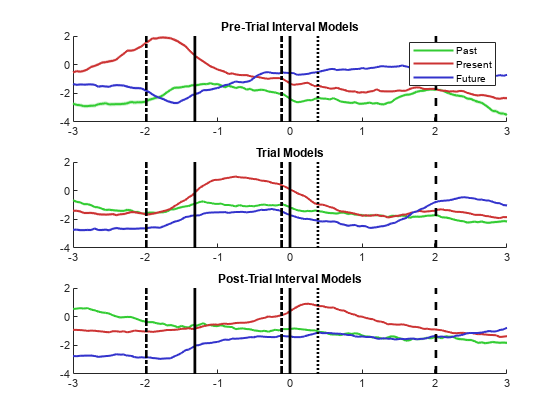

figure;
sp(1) = subplot(3,1,1);
pt(1) = mlb.PlotMeanVarLine(mlb.obsvTimeVect, pstTrPr, 1, 0, [0.2 0.8 0.2]);
pt(2) = mlb.PlotMeanVarLine(mlb.obsvTimeVect, presTrPr, 1, 0, [0.8 0.2 0.2]);
pt(3) = mlb.PlotMeanVarLine(mlb.obsvTimeVect, ftrTrPr, 1, 0, [0.2 0.2 0.8]);
title('Pre-Trial Interval Models');
sp(2) = subplot(3,1,2);
mlb.PlotMeanVarLine(mlb.obsvTimeVect, pstTrTr, 1, 0, [0.2 0.8 0.2]);
mlb.PlotMeanVarLine(mlb.obsvTimeVect, presTrTr, 1, 0, [0.8 0.2 0.2]);
mlb.PlotMeanVarLine(mlb.obsvTimeVect, ftrTrTr, 1, 0, [0.2 0.2 0.8]);
title('Trial Models');
sp(3) = subplot(3,1,3);
mlb.PlotMeanVarLine(mlb.obsvTimeVect, pstTrPo, 1, 0, [0.2 0.8 0.2]);
mlb.PlotMeanVarLine(mlb.obsvTimeVect, presTrPo, 1, 0, [0.8 0.2 0.2]);
mlb.PlotMeanVarLine(mlb.obsvTimeVect, ftrTrPo, 1, 0, [0.2 0.2 0.8]);
title('Post-Trial Interval Models');
linkaxes(sp, 'xy');
for p = 1:length(sp)
    plot(sp(p), repmat(median(cell2mat(trialLIGHTlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(sp(p), repmat(median(cell2mat(trialPIlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(sp(p), repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(sp(p), repmat(median(cell2mat(trialPOlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(sp(p), repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 2);
    if strcmp(endTrialBound, 'RWD')
        plot(sp(p), repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'PO')
        plot(sp(p), repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'RS')
        plot(sp(p), repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    end
    plot(sp(p), repmat(median(cell2mat(trialPIlat(:)')) + median(cell2mat(prevTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
end
legend(pt, [{'Past'}, {'Present'}, {'Future'}]);

## Within vs Between Epoch Decodings

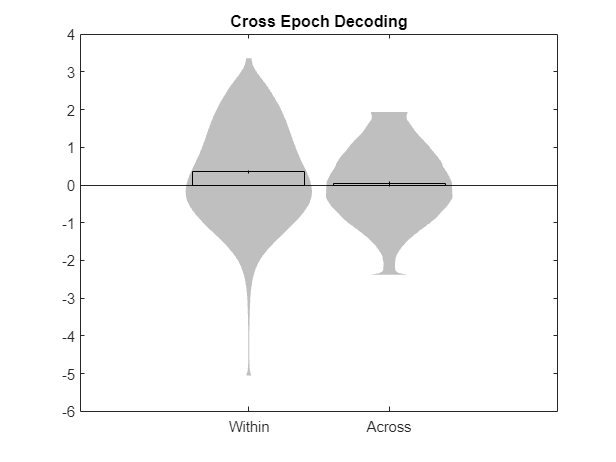

temp_dec_Within = cell2mat(dec_Within(repmat(logical(eye(mlb.seqLength)),[1,1,length(fileDirs)])));
temp_dec_Across = cell2mat(dec_Across(logical(eye(mlb.seqLength))));
figure;
p(1) = mlb.PlotMeanVarViolin(1,temp_dec_Within,1,0.05,'k');
p(2) = mlb.PlotMeanVarViolin(2,temp_dec_Across,1,0.05,'k');
set(gca,'xtick',[1,2],'xticklabels',[{'Within'}, {'Across'}]);
title('Cross Epoch Decoding');

## Model Fits

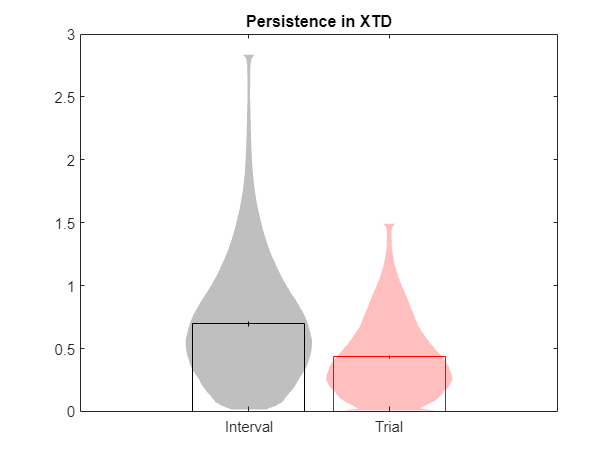

posCollapseLog = logical(eye(mlb.seqLength));
posCollapseLog(1,1) = false;
posCollapseLog(mlb.seqLength,mlb.seqLength) = false;

temp_persFit_Trial = cell2mat(persFit_Trial(repmat(posCollapseLog,[1,1,length(fileDirs)])));
temp_persFit_Interval = cell2mat(persFit_Interval(repmat(posCollapseLog,[1,1,length(fileDirs)])));
% figure;
% mlb.PlotMeanVarLine(1:length(mlb.obsvTimeVect),temp_persFit_Trial,1,0.05,'k');
% mlb.PlotMeanVarLine(1:length(mlb.obsvTimeVect),temp_persFit_Interval,1,0.05,'r');
[~,trialBestFitNdx]=find(temp_persFit_Trial==repmat(min(temp_persFit_Trial,[],2),[1,size(temp_persFit_Trial,2)]));
[~,intervalBestFitNdx]=find(temp_persFit_Interval==repmat(min(temp_persFit_Interval,[],2),[1,size(temp_persFit_Interval,2)]));
intervalPersistDur = objTimeVect(intervalBestFitNdx);
trialPersistDur = objTimeVect(trialBestFitNdx);

figure;
mlb.PlotMeanVarViolin(1,intervalPersistDur,1,0.05,'k');
mlb.PlotMeanVarViolin(2,trialPersistDur,1,0.05,'r');
set(gca, 'xtick', 1:2, 'xticklabels', [{'Interval'}, {'Trial'}]);
title('Persistence in XTD')

## Interval Decoding

% dec_TrPrTsPo
% dec_TrPoTsPr


## Train-Trial & Test Pre-Trial or Post-Trial periods

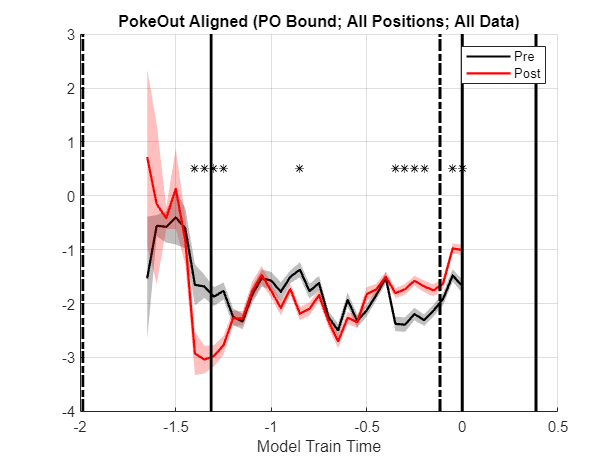

temp_TrlPr = dec_TrTrlTsPr(repmat(posCollapseLog,[1,1,length(fileDirs)]));
temp_TrlPo = dec_TrTrlTsPo(repmat(posCollapseLog,[1,1,length(fileDirs)]));
% temp_TrlPr = dec_TrTrlTsPrCON(repmat(posCollapseLog,[1,1,length(fileDirs)]));
% temp_TrlPo = dec_TrTrlTsPoCON(repmat(posCollapseLog,[1,1,length(fileDirs)]));

figure;
if strcmp(alignment{1}, 'PokeIn')
    xVals = objTimeVect;
elseif strcmp(alignment{1}, 'RewardSignal') || strcmp(alignment{1}, 'PokeOut') || strcmp(alignment{1}, 'FrontReward')
    switch endTrialBound
        case 'RS'
            xVals = objTimeVect-objTimeVect(end) + median(cell2mat(trialSIGlat(:)'));
        case 'PO'
            xVals = objTimeVect-objTimeVect(end) + median(cell2mat(trialPOlat(:)'));
        case 'RWD'
            xVals = objTimeVect-objTimeVect(end) + median(cell2mat(trialRWDlat(:)'));
    end
end
pr = cell2mat(temp_TrlPr);
po = cell2mat(temp_TrlPo);
[p(1),prMTlog] = mlb.PlotMeanVarLine(xVals, pr,1,0,'k');
[p(2),poMTlog] = mlb.PlotMeanVarLine(xVals, po,1,0,'r');
plot(repmat(median(cell2mat(trialLIGHTlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialPIlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialPOlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
mtLog = prMTlog | poMTlog;
pr(:,mtLog) = [];
po(:,mtLog) = [];
xVals(mtLog) = [];
% % Temp fix...
% for t = 1:length(xVals)
%     pr(isnan(pr(:,t)),t) = mean(pr(:,t),'omitnan');
%     po(isnan(po(:,t)),t) = mean(po(:,t),'omitnan');
% end

sigLog = false(1,length(xVals));
for t = 1:length(xVals)
    mtLog = isnan(pr(:,t)) | isnan(po(:,t));
    if sum(mtLog)/length(mtLog) > 0.9
        continue;
    else
        sigLog(t) = ttest(pr(~mtLog,t), po(~mtLog,t), 'Alpha', 0.05/length(mlb.obsvTimeVect));
    end
end
sigLog = sigLog*.5;
sigLog(sigLog==0) = nan;
scatter(xVals', sigLog, '*k');

legend(p, [{'Pre'}, {'Post'}]);
grid on;
xlabel('Model Train Time');
title(sprintf('%s Aligned (%s Bound; All Positions; All Data)', alignment{1}, endTrialBound));

%  title(sprintf('%s Aligned (%s Bound; Interior Positions Only; All Data)', alignment{1}, endTrialBound));


## Examine Symmetry in XTD

symRatTR = cell(mlb.seqLength, 1);
symRatDEC = cell(mlb.seqLength, 1);
symRatMN = cell(mlb.seqLength, 1);
for p1 = 1:mlb.seqLength
    tempDs = groupDs{p1,p1};
    temp_symRatTR = nan(size(tempDs,3),length(mlb.obsvTimeVect));
    temp_symRatDEC = nan(size(tempDs,3),length(mlb.obsvTimeVect));
    temp_symRatMN = nan(size(tempDs,3),length(mlb.obsvTimeVect));
    for trl = 1:size(tempDs,3)
        temp_trialD = tempDs(:,:,trl);
        for t = 10:length(mlb.obsvTimeVect)-10
            %                 trVect = temp_trialD(:,t);
            %                 decVect = temp_trialD(t,:);
            trVect = smooth(temp_trialD(:,t),'lowess');
            decVect = smooth(temp_trialD(t,:),'lowess');
            mnVect = mean([trVect(:), decVect(:)],2,'omitnan');
            if trVect(t)>0
                fwdTRlag = find(trVect(t:end)<=0,1,'first');
                if isempty(fwdTRlag)
                    fwdTRlag = length(trVect)-t;
                end
                revTRlag = find(trVect(1:t)<=0,1,'last');
                if isempty(revTRlag)
                    revTRlag = t;
                else
                    revTRlag = t-revTRlag;
                end
                temp_symRatTR(trl,t) = fwdTRlag - revTRlag;
            end
            if decVect(t)>0
                fwdDEClag = find(decVect(t:end)<=0,1,'first');
                if isempty(fwdDEClag)
                    fwdDEClag = length(decVect)-t;
                end
                revDEClag = find(decVect(1:t)<=0,1,'last');
                if isempty(revDEClag)
                    revDEClag = t;
                else
                    revDEClag = t-revDEClag;
                end
                temp_symRatDEC(trl,t) = fwdDEClag - revDEClag;
            end
            if mnVect(t)>0
                fwdMNlag = find(mnVect(t:end)<=0,1,'first');
                if isempty(fwdMNlag)
                    fwdMNlag = length(decVect)-t;
                end
                revMnLag = find(mnVect(1:t)<=0,1,'last');
                if isempty(revMnLag)
                    revMnLag = t;
                else
                    revMnLag = t-revMnLag;
                end
                temp_symRatMN(trl,t) = fwdMNlag - revMnLag;
            end
        end
    end
    symRatTR{p1} = temp_symRatTR;
    symRatDEC{p1} = temp_symRatDEC;
    symRatMN{p1} = temp_symRatMN;
end


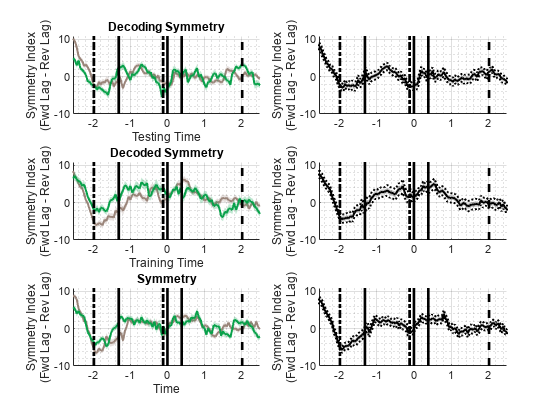


figure;
sps = nan(3,2);
% for p = 1:mlb.seqLength
for p = 2:mlb.seqLength-1
    sps(1) = subplot(3,2,1);
    tempTR = symRatTR{p};
    %     tempTR = (tempTR - mean(tempTR(:),'omitnan')) ./ std(tempTR(:),'omitnan');
    mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempTR,1,0,mlb.PositionColors(p,:));
    sps(2) = subplot(3,2,3);
    tempDEC = symRatDEC{p};
    %     tempDEC = (tempDEC - mean(tempDEC(:),'omitnan')) ./ std(tempDEC(:),'omitnan');
    mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempDEC,1,0,mlb.PositionColors(p,:));
    sps(3) = subplot(3,2,5);
    tempMN = symRatMN{p};
    %     tempMN = (tempMN - mean(tempMN(:),'omitnan')) ./ std(tempMN(:),'omitnan');
    mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempMN,1,0,mlb.PositionColors(p,:));
end
sps(4) = subplot(3,2,2);
% tempTR = cell2mat(symRatTR);
tempTR = cell2mat(symRatTR(2:mlb.seqLength-1));
% tempTR = (tempTR - mean(tempTR(:),'omitnan')) ./ std(tempTR(:),'omitnan');
mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempTR,1,0.05,'k');
sps(5) = subplot(3,2,4);
% tempDEC = cell2mat(symRatDEC);
tempDEC = cell2mat(symRatDEC(2:mlb.seqLength-1));
% tempDEC = (tempDEC - mean(tempDEC(:),'omitnan')) ./ std(tempDEC(:),'omitnan');
mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempDEC,1,0.05,'k');
sps(6) = subplot(3,2,6);
% tempMN = cell2mat(symRatMN);
tempMN = cell2mat(symRatMN(2:mlb.seqLength-1));
% tempMN = (tempMN - mean(tempMN(:),'omitnan')) ./ std(tempMN(:),'omitnan');
mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempMN,1,0.05,'k');
linkaxes(sps,'xy');

for plt = 1:6
    subplot(3,2,plt);
    if plt==1
        title('Decoding Symmetry');
        xlabel('Testing Time');
    elseif plt==3
        title('Decoded Symmetry');
        xlabel('Training Time');
    elseif plt==5
        title('Symmetry');
        xlabel('Time');
    end
    ylabel([{'Symmetry Index'};{'(Fwd Lag - Rev Lag)'}]);
    plot(repmat(median(cell2mat(trialLIGHTlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialPIlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialPOlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);

    if strcmp(endTrialBound, 'RWD')
        plot(repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'PO')
        plot(repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'RS')
        plot(repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    end
    plot(repmat(median(cell2mat(trialPIlat(:)')) + median(cell2mat(prevTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    grid on;
    grid minor;
end

## Fucking beta power again I guess